# Motion Architectures

## Tricycle vehicle

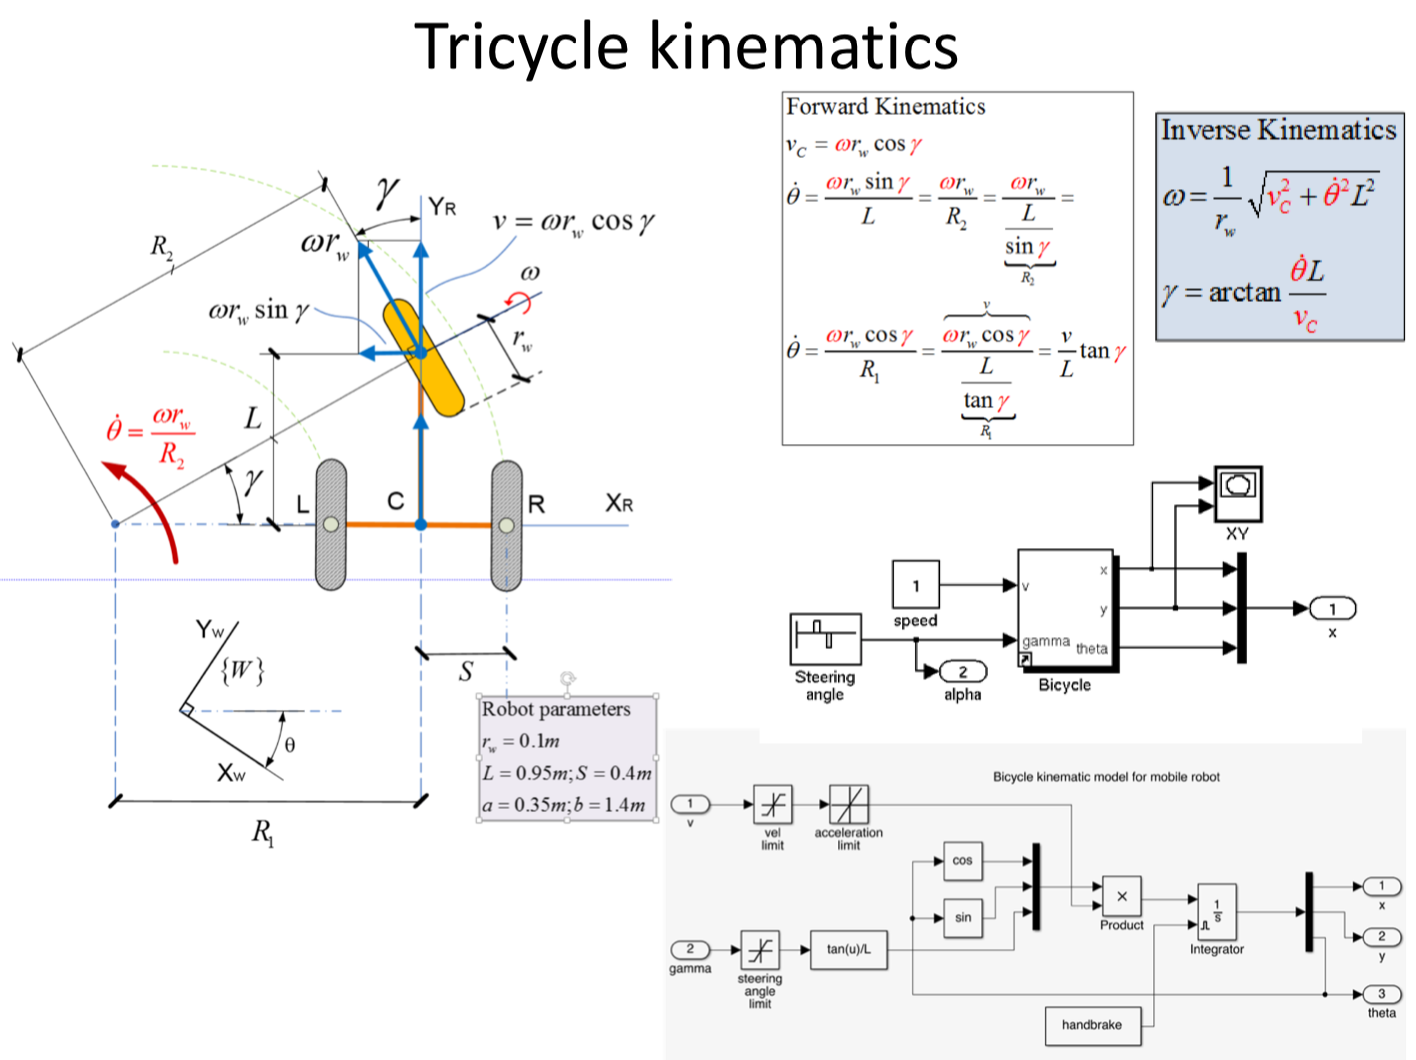

## Lane change

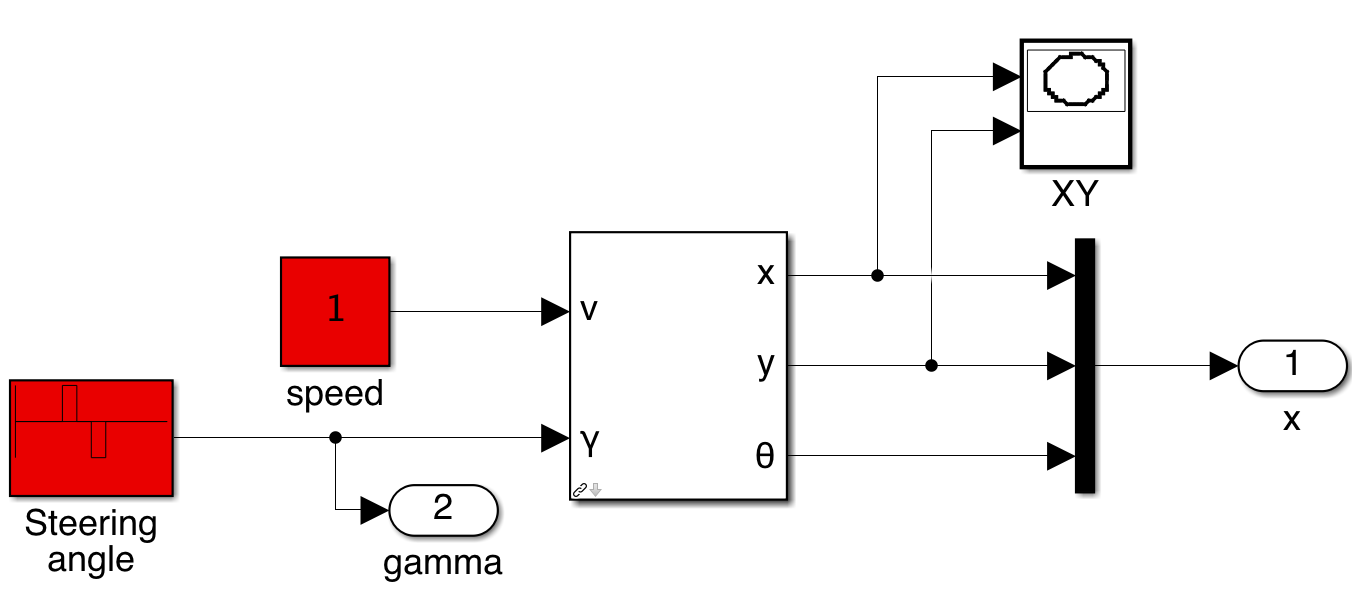

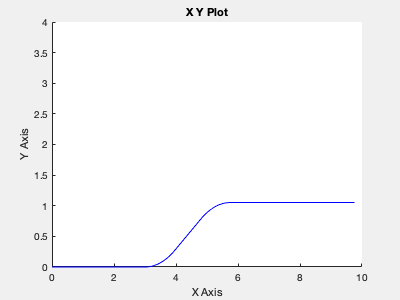

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


clear
sl_lanechange
out=sim("sl_lanechange.slx")

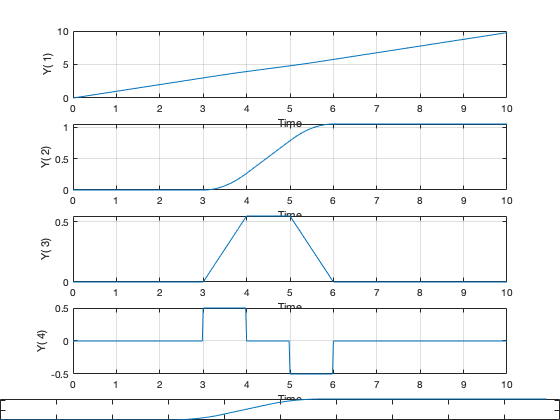

t = out.get('t'); q = out.get('y');
mplot(t, q)
plot(q(:,1), q(:,2))

## Moving to a point

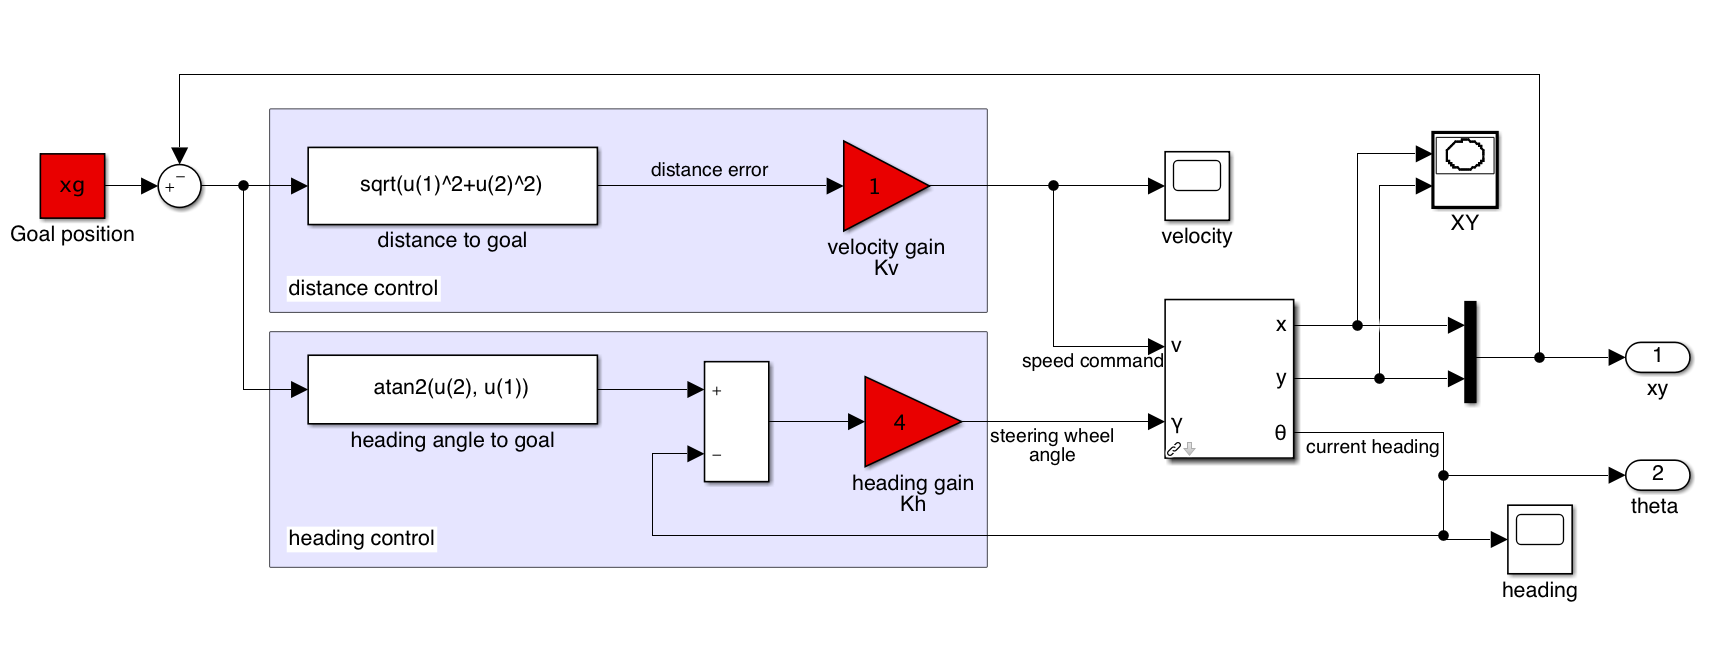

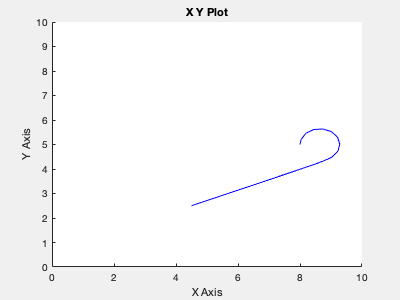

r1 =   Simulink.SimulationOutput:

                      t: [55x1 double] 
                      y: [55x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


clear
sl_drivepoint
xg = [4.5 2.5];
x0 = [8 5 pi/2];
r1=sim("sl_drivepoint.slx") % Call and run the Simulink Model

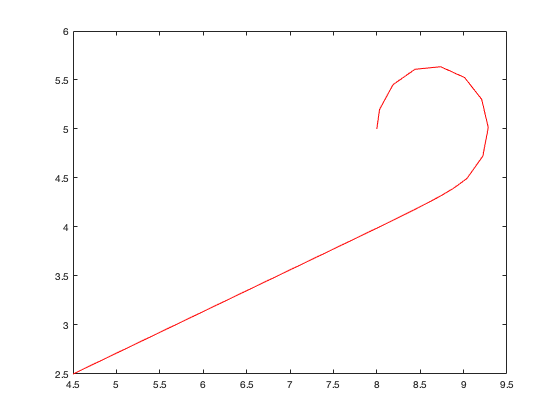

q_05_4= r1.find('y');
plot(q_05_4(:,1), q_05_4(:,2),'r');
hold on

## Following a line

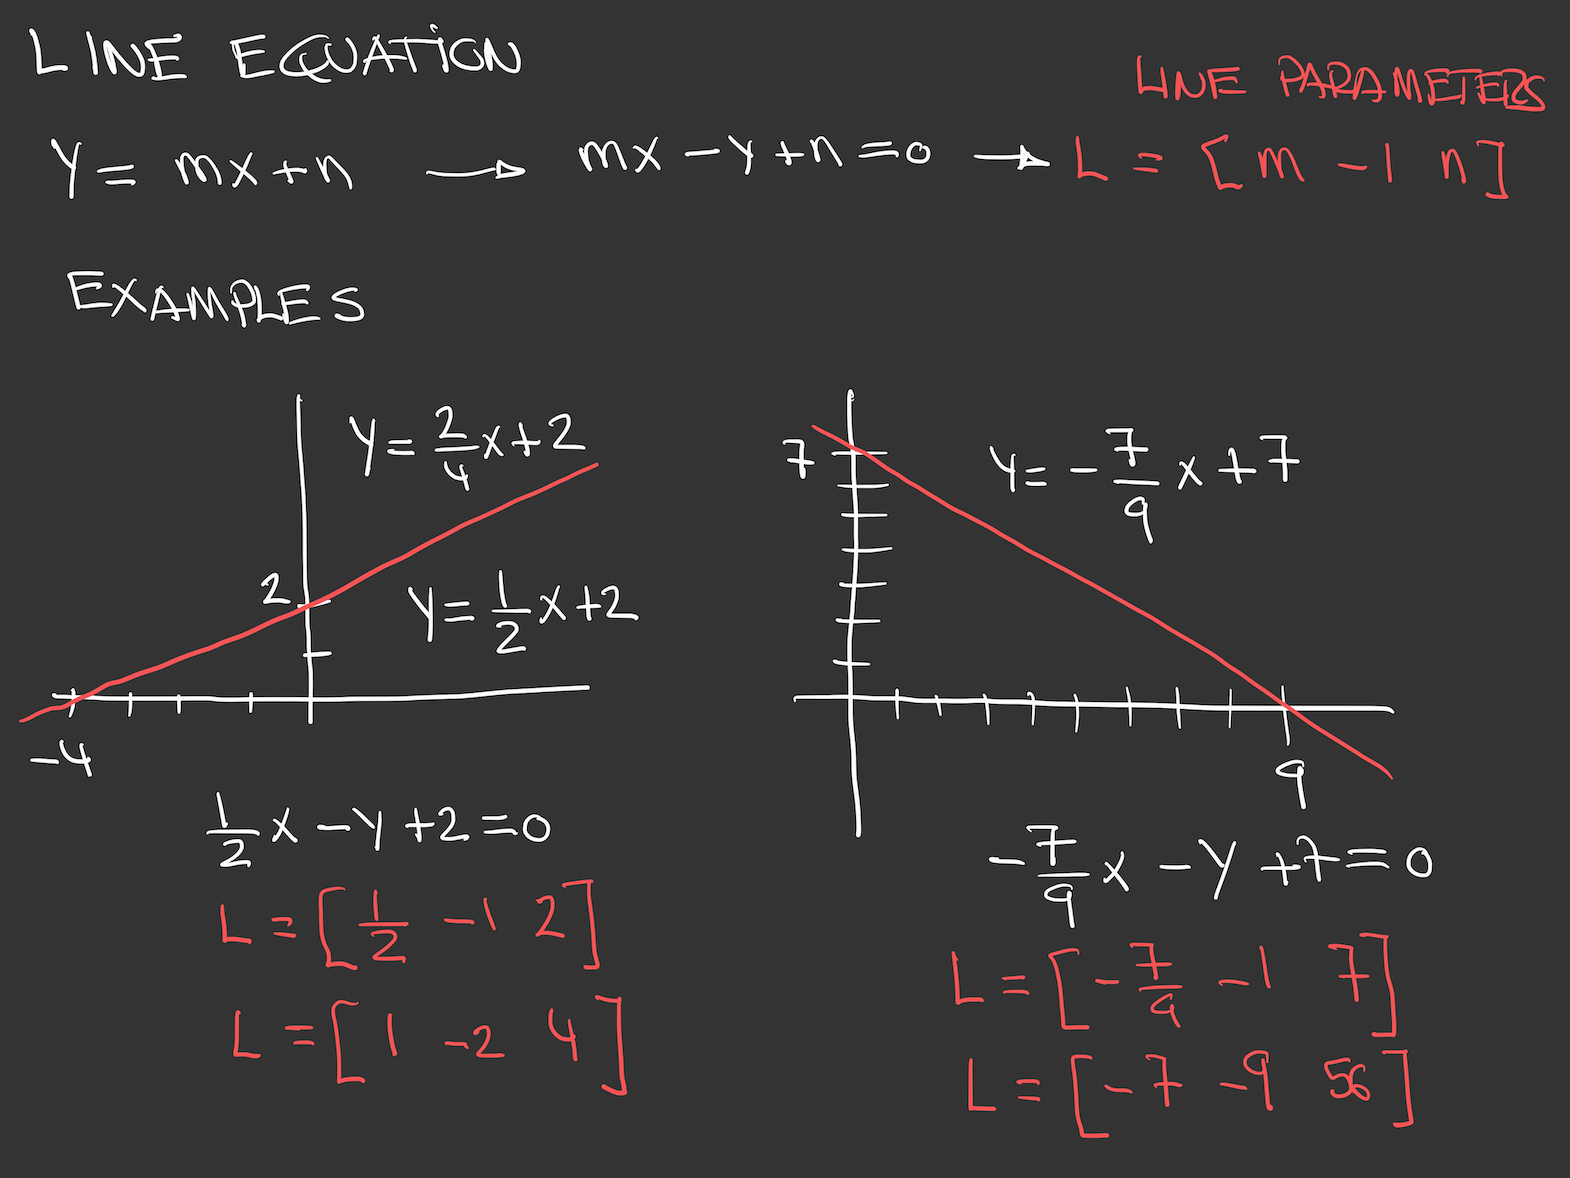

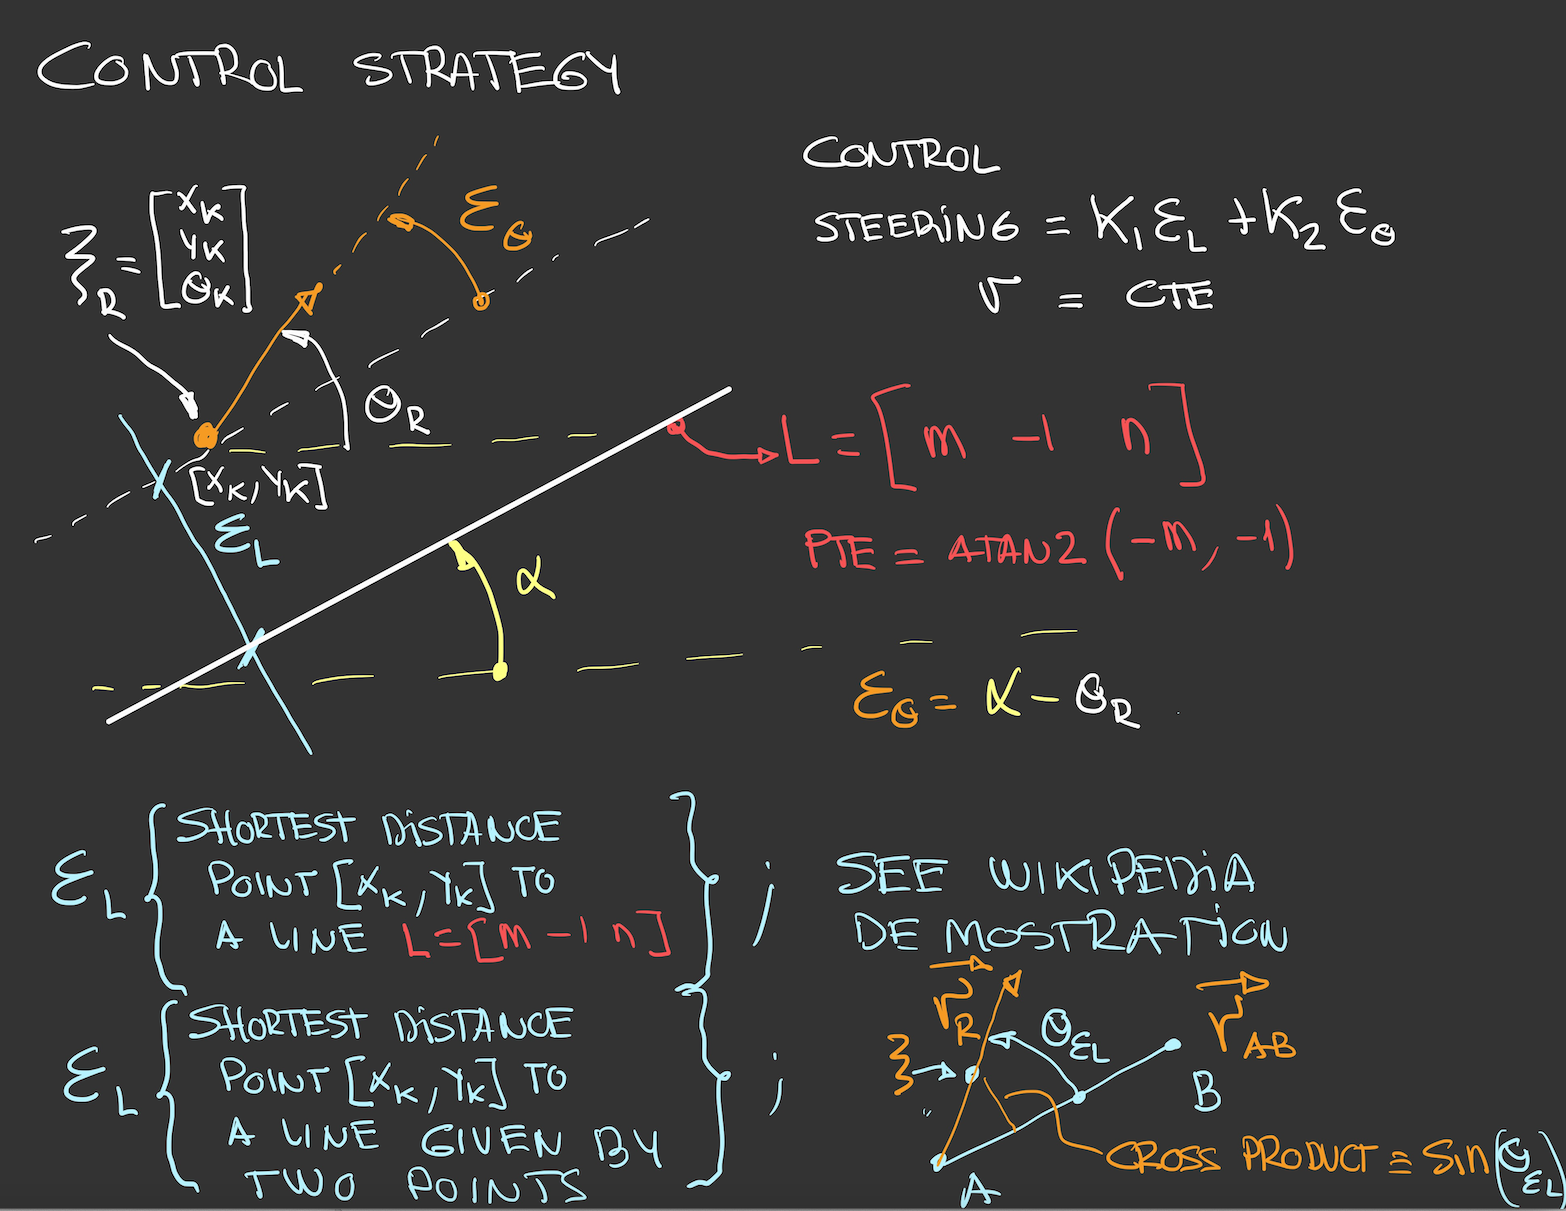

### Lateral error: Shortest distance

At instant k

L_p_A= [1 2] % Point A of the Line

L_p_A =      1     2


L_p_B= [4 2] % Point B of the line

L_p_B =      4     2


L_p_R= [1.5 4]% Point of the robot a instant k

L_p_R =     1.5000    4.0000


Plotting

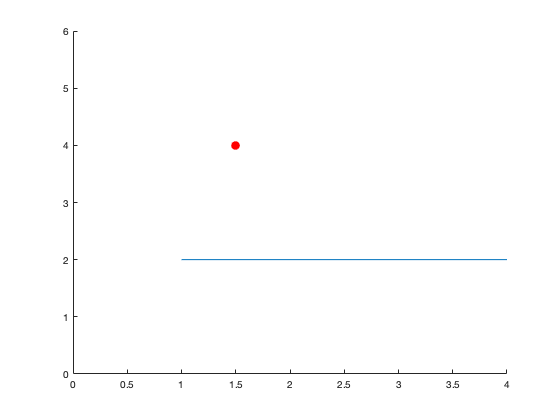

figure 
line([L_p_A(1) L_p_B(1)],[L_p_A(2) L_p_B(2)])
hold on
plot(L_p_R(1), L_p_R(2),'r.','MarkerSize',30 )
axis ([0 4 0 6])

Compunting shortest distance


$$
  \overrightarrow {AB}  \times \overrightarrow {AR}  = \left| {\overrightarrow {AB} } \right|\left| {\overrightarrow {AR} } \right|\sin ({\theta _{\varepsilon L}}) \\
  d = \left\| {\overrightarrow {AR} } \right\|\sin ({\theta _{\varepsilon L}}) \\ 
\end{gathered} \]$$


v_A_B=[ L_p_B(1)- L_p_A(1);...
        L_p_B(2)- L_p_A(2); 0]

v_A_B =      3
     0
     0


v_A_R=[(L_p_R(1)- L_p_A(1));...
       (L_p_R(2)- L_p_A(2));0]

v_A_R =     0.5000
    2.0000
         0


AXB=cross(v_A_B,v_A_R)

AXB =      0
     0
     6


sin_th_l=AXB(3)/(norm(v_A_B)*norm(v_A_R))

sin_th_l = 0.9701

d=norm(v_A_R)*sin_th_l

d = 2

clear
sl_driveline
x0=[8 5 0]
L = [-7 -9 63]; 
sim("sl_driveline.slx")

## Following a trajectory

Read Chapter 4 of the Peter corke Book

## Moving to a pose

Read Chapter 4 of the Peter corke Book